checking 'create_new_database' reads GLASS HDF files in specified folder

    creates table with time of data, file location, and id's of good profiles

    checking rm_cld will filter out profiles with clouds from good profiles

    the table is save to specified location to be used later

clc; clearvars;

addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\proc_functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\functions"));

folder = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\GLASS";

files = dir(fullfile(folder,"*.hdf"));

info = hdfinfo(fullfile(folder,files(1).name));
n = length(info.SDS);
for i = 1:n
    SDS_temp = info.SDS(i);

    disp(SDS_temp.Name)
end

LATITUDE.INSTRUMENT
LONGITUDE.INSTRUMENT
ALTITUDE.INSTRUMENT
DATETIME
DATETIME.START
DATETIME.STOP
INTEGRATION.TIME
ALTITUDE
O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL
O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL_UNCERTAINTY.COMBINED.STANDARD
O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL_UNCERTAINTY.RANDOM.STANDARD
O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL_UNCERTAINTY.SYSTEMATIC.STANDARD
O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL_RESOLUTION.ALTITUDE.IMPULSE.RESPONSE.FWHM
O3.MIXING.RATIO.VOLUME_DERIVED
O3.MIXING.RATIO.VOLUME_DERIVED_UNCERTAINTY.COMBINED.STANDARD
O3.MIXING.RATIO.VOLUME_DERIVED_UNCERTAINTY.RANDOM.STANDARD
O3.MIXING.RATIO.VOLUME_DERIVED_UNCERTAINTY.SYSTEMATIC.STANDARD
PRESSURE_INDEPENDENT
TEMPERATURE_INDEPENDENT
PRESSURE_INDEPENDENT_SOURCE
TEMPERATURE_INDEPENDENT_SOURCE


n_files = length(files);

save_name = "glass_profiles_cldrem.mat";
save_folder = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\dir";

create_new_database = true;
rm_cld = true;

if create_new_database==1
    glass_dataset = table;

    count = 0;
    for k = 1:n_files
        file = fullfile(folder, files(k).name);
    
        dt = hdfread(file,"DATETIME");
        dt_start = hdfread(file,"DATETIME.START");
        dt_stop = hdfread(file,"DATETIME.STOP");
        N = hdfread(file,"O3.NUMBER.DENSITY_ABSORPTION.DIFFERENTIAL");
        p = hdfread(file,"PRESSURE_INDEPENDENT"); % hPa
        t = hdfread(file,"TEMPERATURE_INDEPENDENT"); % k
    
        p = p';
        t = t';
    
        N(N<0) = NaN;
        N = N';
        
        max_row = size(N,1);
        
        N_good = NaN(size(N));
        n_prof = size(N,2);
        id_good = [];
        
        ct_good = 0;
        for i = 1:n_prof
            temp_prof = N(:,i);
    
            if all(isnan(temp_prof))
                continue
            end
        
            good = true;
            if rm_cld==1
                id_nan = find(isnan(temp_prof));
                for j = 1:length(id_nan)
                    if id_nan(j) == max_row
                        break
                    end
            
                    if ~isnan(temp_prof(id_nan(j)+1))
                        good = false;
                        break;
                    end
                end
            end
            
            if good == true
                N_good(:,ct_good+1) = temp_prof;
                id_good(end+1) = i;
                ct_good = ct_good + 1;
            end
        end
    
        if ct_good==0
            continue
        end
        count = count+1;

        id_good = {id_good};
        time = dt(1);

        dataset_temp = table(time, file, id_good);
        glass_dataset = [glass_dataset; dataset_temp];
    end
    save(fullfile(save_folder,save_name),"glass_dataset");

else
    load(fullfile(save_folder,save_name))
end

id =18;

test_glass = read_glass(glass_dataset.file(id));
idx_good = cell2mat(glass_dataset.id_good(id));

N_glass = test_glass.N';
alt = test_glass.alt;
alt_inst = test_glass.alt_inst;
time = test_glass.dt;

N_glass(N_glass<0) = NaN;

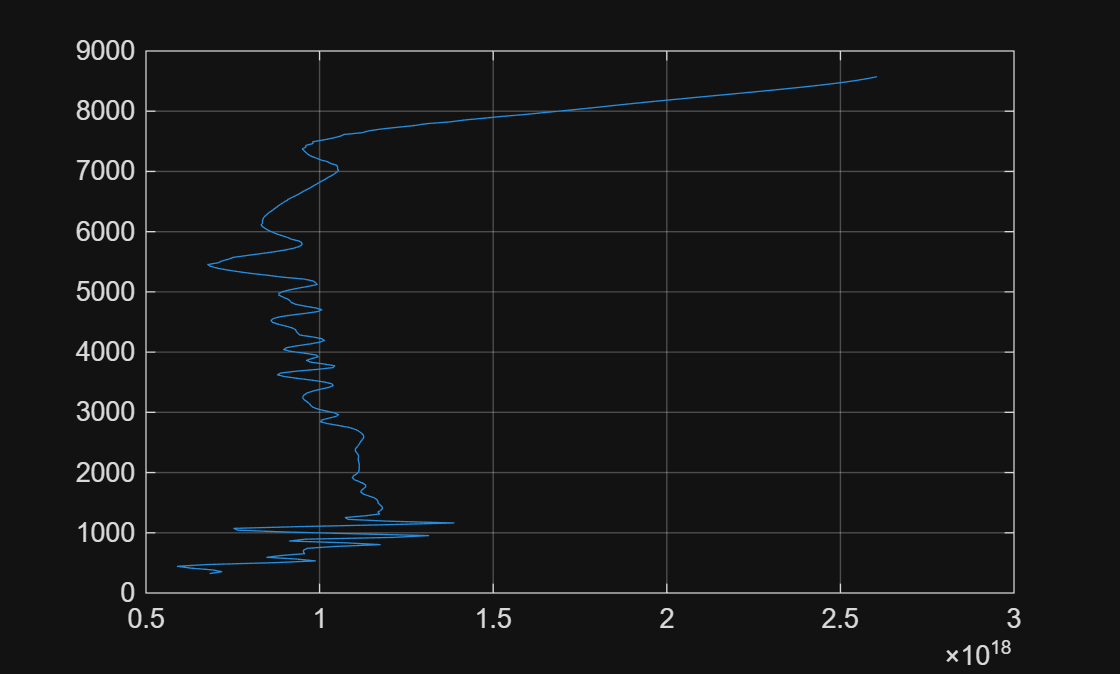

n_prof = length(idx_good);
idx = 6;
prof = idx_good(idx);
N_glass_prof = N_glass(:,prof);

figure;
plot(N_glass_prof,alt)
grid on

% Extend altitude grid and ozone vector down to lidar
alt_lower = alt_inst:30:min(alt);
alt_ext = [alt_lower alt];

N_ext = [zeros(length(alt_lower), n_prof); N_glass(:,idx_good)];

% Fill missing values in GLASS data
N_ext = fillmissing(N_ext,"linear",1,"EndValues",0);

% Ozone Absorption Cross Section
BDM = load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\cross_sections\ozone\bdm\bdm_287_299.mat");

o3_287 = BDM.BDM_c287(1) .* 1e-4; % use first temp dependent cross section for now
o3_299 = BDM.BDM_c299(1) .* 1e-4;

do3 = BDM.BDM_d_287_299(1) .* 1e-4;

% Air Number Density
Nair = airNumberDensity(alt_ext);

sigma_m_on = rayleigh_cross_section(287.2e-9);   
sigma_m_off = rayleigh_cross_section(299.1e-9);   
dsigma_m = sigma_m_on - sigma_m_off;

D_No3 = dsigma_m .* Nair ./ do3;

% Prepare parameters for signal calculation
E0_287 = 10.6e-3;
E0_299 = 6.3e-3;

eta_287 = 1/53.1572075; % Efficiency factor
eta_299 = 1/47.0176125; % 

etaQ = 0.7;

t_r = .2;   % Radius of the receiver in meters
o_r = 0.1;  % Radius of the obstruction
tau = 6e-9; % Laser pulse duration

% Calculate the signal using the defined parameters
[N_287,K_287,G_287,B_287,T_287] = signal(alt_ext,alt_inst,287.2e-9,E0_287,t_r,o_r,tau,eta_287,etaQ,Nair,o3_287,N_ext); 

Error using signal
Too many input arguments.

[N_299,K_299,G_299,B_299,T_299] = signal(alt_ext,alt_inst,299.1e-9,E0_299,t_r,o_r,tau,eta_299,etaQ,Nair,o3_299,N_ext); 

N_287(1:length(alt_lower),:) = [];
N_299(1:length(alt_lower),:) = [];

save("./sim_prof.mat","N_287","N_299","alt");

figure;
plot(alt_ext,T_287(:,idx))
xlabel("altitude (m)")
ylabel("Transmittance")
grid on
figure;
semilogy(alt,N_287(:,idx),'DisplayName','287')
hold on
semilogy(alt,N_299(:,idx),'DisplayName','299')
grid on
legend
xlim([0 2e3])

dr = NaN(length(alt)-1,1);
for i = 1:length(alt)-1
    dr(i) = alt(i+1) - alt(i);
end

s = log(N_299./N_287);
S = diff(s)./dr;
N_sim = S./(2*do3)' - D_No3(length(alt_lower)+1:end-1)';

figure;
plot(N_sim(:,idx),alt(1:end-1),'DisplayName','Simulated','LineWidth',2)
hold on
plot(N_glass_prof,alt,'DisplayName','GLASS','LineStyle','--','LineWidth',2)
legend

Clim = [.6e18 2e18];

figure
imagesc(time(:,idx_good),alt,N_glass(:,idx_good))
colorbar
set(gca,'YDir','normal')
xlabel('Time (UTC)')
title('GLASS')
clim(Clim)
figure
imagesc(time(:,idx),alt,N_sim)
colorbar
set(gca,'YDir','normal')
xlabel('Time (UTC)')
title('Simulated')
clim(Clim)